# Laboratorio di Automatica (prova del 12 Giugno 2018)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

June 12, 2018

Dept. of Information Engineering, University of Padova

## Esercizio 2

Si consideri il sistema di controllo di posizione di un motore elettrico in corrente continua mostrato in Fig. 1, dove 


$$P(s)\,=\, \frac{Y(s)}{U(s)} \,=\, \frac{k_m}{s(T_m s  + 1)}
\qquad\quad\text{con}\qquad\quad
k_m\,=\,5.2\,,\qquad T_m \,=\,0.03$$


è la funzione di trasferimento del motore, da ingresso in tensione $u$ $[V]$ ad uscita in posizione $y$ $[\mathrm{rad}]$, mentre 


$$C(s) \,=\, \frac{U(s)}{E(s)} \,=\; 
K_P \,+\, \frac{K_I}{s} \,+\, \frac{K_D\,s}{T_L\,s\,+\,1} $$


con 


$$K_P \,=\, 8.7\,,\qquad
K_I \,=\, 120.0\,,\qquad
K_D \,=\, 0.16\,,\qquad
T_L \,=\, 0.0053$$


è la funzione di trasferimento di un controllore PID (con derivata "reale"), con ingresso l'errore di posizione $e\,[\mathrm{rad}]$ ed uscita la tensione di comando $u\,[\mathrm{V}]$.

**Figura 1**: controllo di posizione con controllore PID.

Utilizzando esclusivamente le routine del *Control System Toolbox (CST)*, si svolgano i seguenti punti:

1)  Ricavare le seguenti funzioni di trasferimento:

- funzione di trasferimento $T_1(s)=Y(s)/R(s)$ da segnale di riferimento $r$ ad uscita $y$

- funzione di trasferimento $G_1(s) = Y(s)/D(s)$ da disturbo di carico $d$ ad uscita $y$

- funzione di trasferimento $W_1(s) = U(s)/R(s)$ da riferimento $r$ a tensione di comando $u$

*Soluzione*.

%   plant tf
sysP = tf(5.2, [0.03, 1, 0]);

%   controller params
Kp = 8.7;
Ki = 120.0;
Kd = 0.16;
TL = 0.0053;

%   controller tfs
sysC_PI = Kp + tf(Ki, [1,0]);
sysC_D = tf([Kd, 0], [TL, 1]);
sysC_PID = sysC_PI + sysC_D;

%   loop tf
sysL1 = sysC_PID*sysP;

%   sensitivity tf
sysS1 = 1/(1+sysL1);

%   closed-loop tf
sysT1 = zpk( minreal( feedback(sysC_PID*sysP, 1) ) )


sysT1 =
 
         6740.7 (s^2 + 45.3s + 582.2)
  ------------------------------------------
  (s+145.7) (s+48.31) (s^2 + 28.01s + 557.6)
 
Continuous-time zero/pole/gain model.




%   disturbance-to-output tf
sysG1 = zpk( minreal( sysP*sysS1 ) )


sysG1 =
 
              173.33 s (s+188.7)
  ------------------------------------------
  (s+145.7) (s+48.31) (s^2 + 28.01s + 557.6)
 
Continuous-time zero/pole/gain model.




%   reference-to-control-command tf
sysW1 = zpk( minreal( sysC_PID*sysS1 ) )


sysW1 =
 
   38.889 s (s+33.33) (s^2 + 45.3s + 582.2)
  ------------------------------------------
  (s+145.7) (s+48.31) (s^2 + 28.01s + 557.6)
 
Continuous-time zero/pole/gain model.



2)  Mostrare (in tre figure distinte) le risposte al gradino unitario dei sistemi con funzioni di trasferimento $T_1(s)$, $G_1(s)$ e $W_1(s)$.

*Soluzione*.

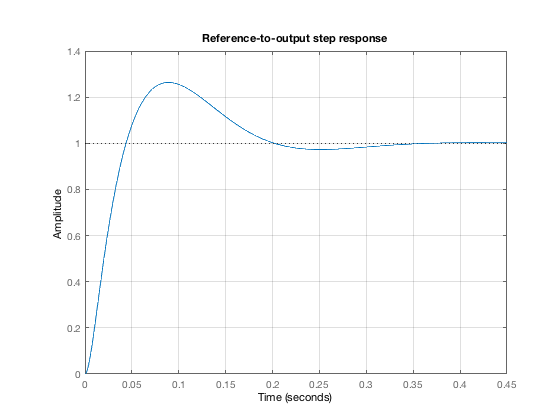

%   reference-to-output step response
figure(1);
step(sysT1);
grid on;
title('Reference-to-output step response');

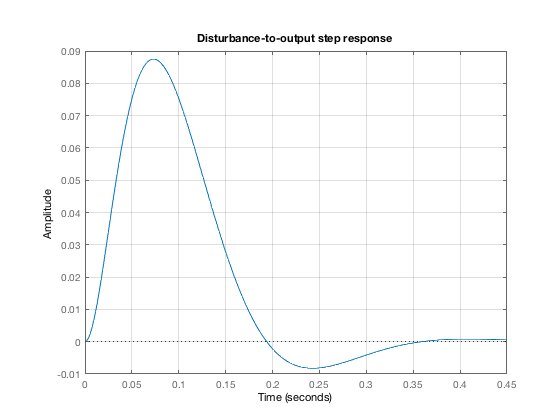


%   disturbance-to-output step response
figure(2);
step(sysG1);
grid on;
title('Disturbance-to-output step response');

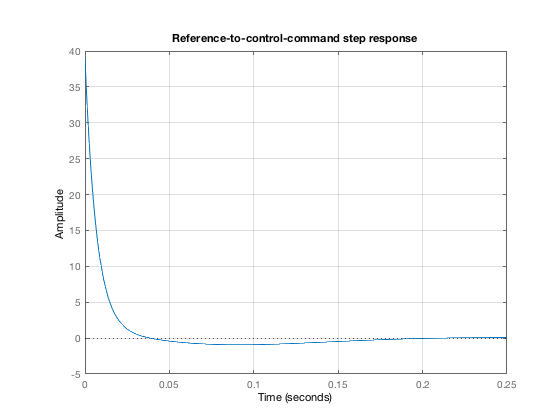


%   Disturbance-to-output step response
figure(3);
step(sysW1);
grid on;
title('Reference-to-control-command step response');

3)  Si consideri lo schema di controllo alternativo mostrato in Fig. 2, dove

$C_1(s) \,=\, 
K_P \,+\, \frac{K_I}{s}$   ,       $C_2(s) \;=\; \frac{K_D\,s}{T_L\,s\,+\,1} $

che corrisponde ad una configurazione di tipo PI-D (il termine derivativo del controllore PID è posto sul ramo di retroazione, anzichè sul ramo diretto).

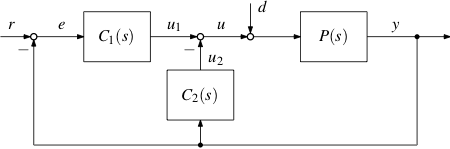

**Figura 2**: controllo di posizione con controllore PI-D.

In modo analogo a quanto fatto nel punto 1, si ricavino le funzioni di trasferimento da riferimento ad uscita ( $T_2(s)$ ), da disturbo ad uscita ( $G_2(s)$ ) e da riferimento a tensione di comando ( $W_2(s)$ ). 

*Soluzione*.

%   loop tf
sysL2 = sysL1;

%   sensitivity tf
sysS2 = sysS1;

%   closed-loop tf
sysT2 = zpk( minreal( sysC_PI*sysP*sysS2 ) )


sysT2 =
 
           1508 (s+188.7) (s+13.79)
  ------------------------------------------
  (s+145.7) (s+48.31) (s^2 + 28.01s + 557.6)
 
Continuous-time zero/pole/gain model.




%   disturbance-to-output tf
sysG2 = zpk( minreal( sysP*sysS2 ) )


sysG2 =
 
              173.33 s (s+188.7)
  ------------------------------------------
  (s+145.7) (s+48.31) (s^2 + 28.01s + 557.6)
 
Continuous-time zero/pole/gain model.




%   reference-to-control-command tf
sysW2 = zpk( minreal( sysC_PI*sysS2 ) )


sysW2 =
 
     8.7 s (s+188.7) (s+33.33) (s+13.79)
  ------------------------------------------
  (s+145.7) (s+48.31) (s^2 + 28.01s + 557.6)
 
Continuous-time zero/pole/gain model.



4)  Mostrare (sovrapposte alle corrispondenti figure ottenute al punto 2) le risposte al gradino unitario dei sistemi con funzioni di trasferimento $T_2(s)$, $G_2(s)$ e $W_2(s)$.

Dal confronto delle risposte ottenute con le due configurazioni di tipo PID e PI-D, quali considerazioni si possono trarre a riguardo del comando di tensione richiesto per assolvere al problema di regolazione della posizione ? E per quanto riguarda la reiezione al disturbo ?

*Soluzione*.

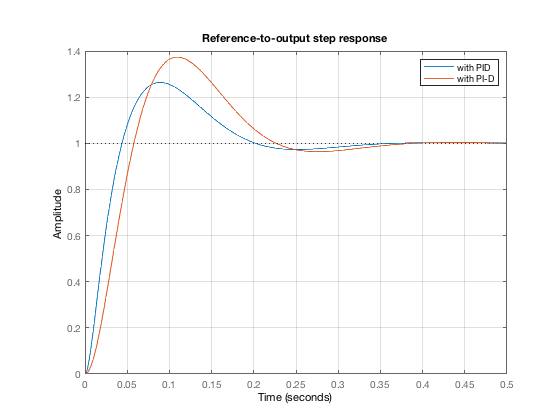

%   closed-loop step response
figure(1);
hold on;
step(sysT2);
legend('with PID', 'with PI-D');

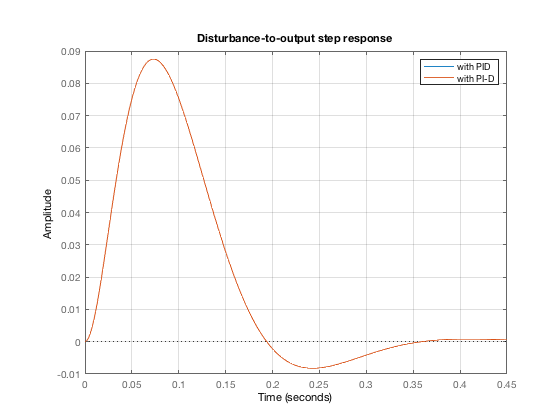


%   response to step disturbance
figure(2);
hold on;
step(sysG2);
legend('with PID', 'with PI-D');

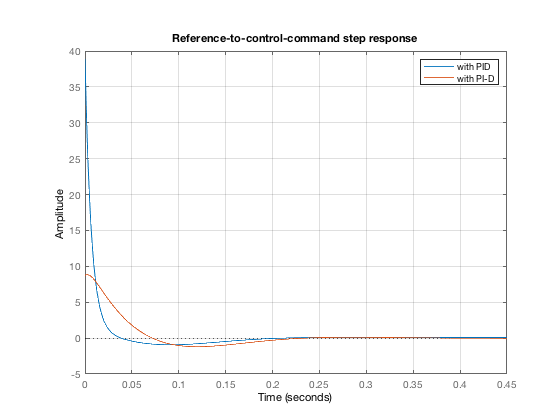


%   response to step disturbance
figure(3);
hold on;
step(sysW2);
legend('with PID', 'with PI-D');

Nella configurazione PI-D, il segnale di riferimento non viene derivato dal blocco derivatore. Di conseguenza, la discontinuità del rferimento non produce segnali di comando di tipo impusivo, come invece succede nel caso della configurazione PID.

Per quanto riguarda la reiezione al disturbo, le due configurazioni PI-D e PID hanno medesima funzione di trasferimento da disturbo ad uscita, e pertanto presentano le medesime proprietà di reiezione. 

5)  Calcolare poli e zeri delle funzioni di trasferimento $T_1(s)$ e $T_2(s)$, e mostrarli poi sul piano complesso.

*Soluzione*.

%   closed-loop poles and zeros
pole(sysT1)

ans = 	1.0e+02 *

  -1.4569 + 0.0000i
  -0.4831 + 0.0000i
  -0.1401 + 0.1901i
  -0.1401 - 0.1901i


zero(sysT1)

ans =  -22.6481 + 8.3233i
 -22.6481 - 8.3233i



%   closed-loop poles and zeros
pole(sysT2)

ans = 	1.0e+02 *

  -1.4569 + 0.0000i
  -0.4831 + 0.0000i
  -0.1401 + 0.1901i
  -0.1401 - 0.1901i


zero(sysT2)

ans =  -188.6792
  -13.7931


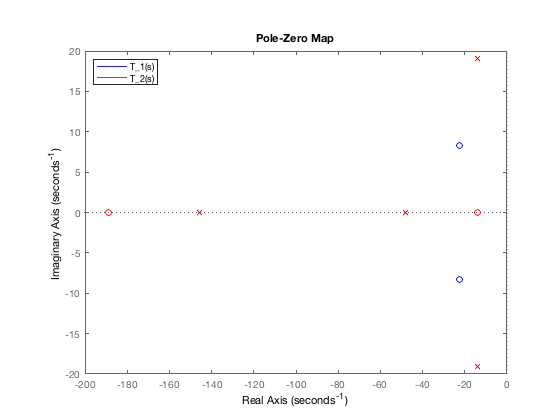


%   pole-zero map
figure;
pzmap(sysT1, 'b');
hold on;
pzmap(sysT2, 'r');
hl = legend('T_1(s)', 'T_2(s)');
set(hl, 'Location', 'NorthWest');

Si noti che $T_1(s)$ e $T_2(s)$ hanno gli stessi poli, ma zeri diversi. Gli zeri modificano la risposta in transitorio, e ciò spiega le differenti risposte a gradino ottenute in precedenza.